## Przygotowanie wzorcowych wektorów cech

### Wczytanie nagrania

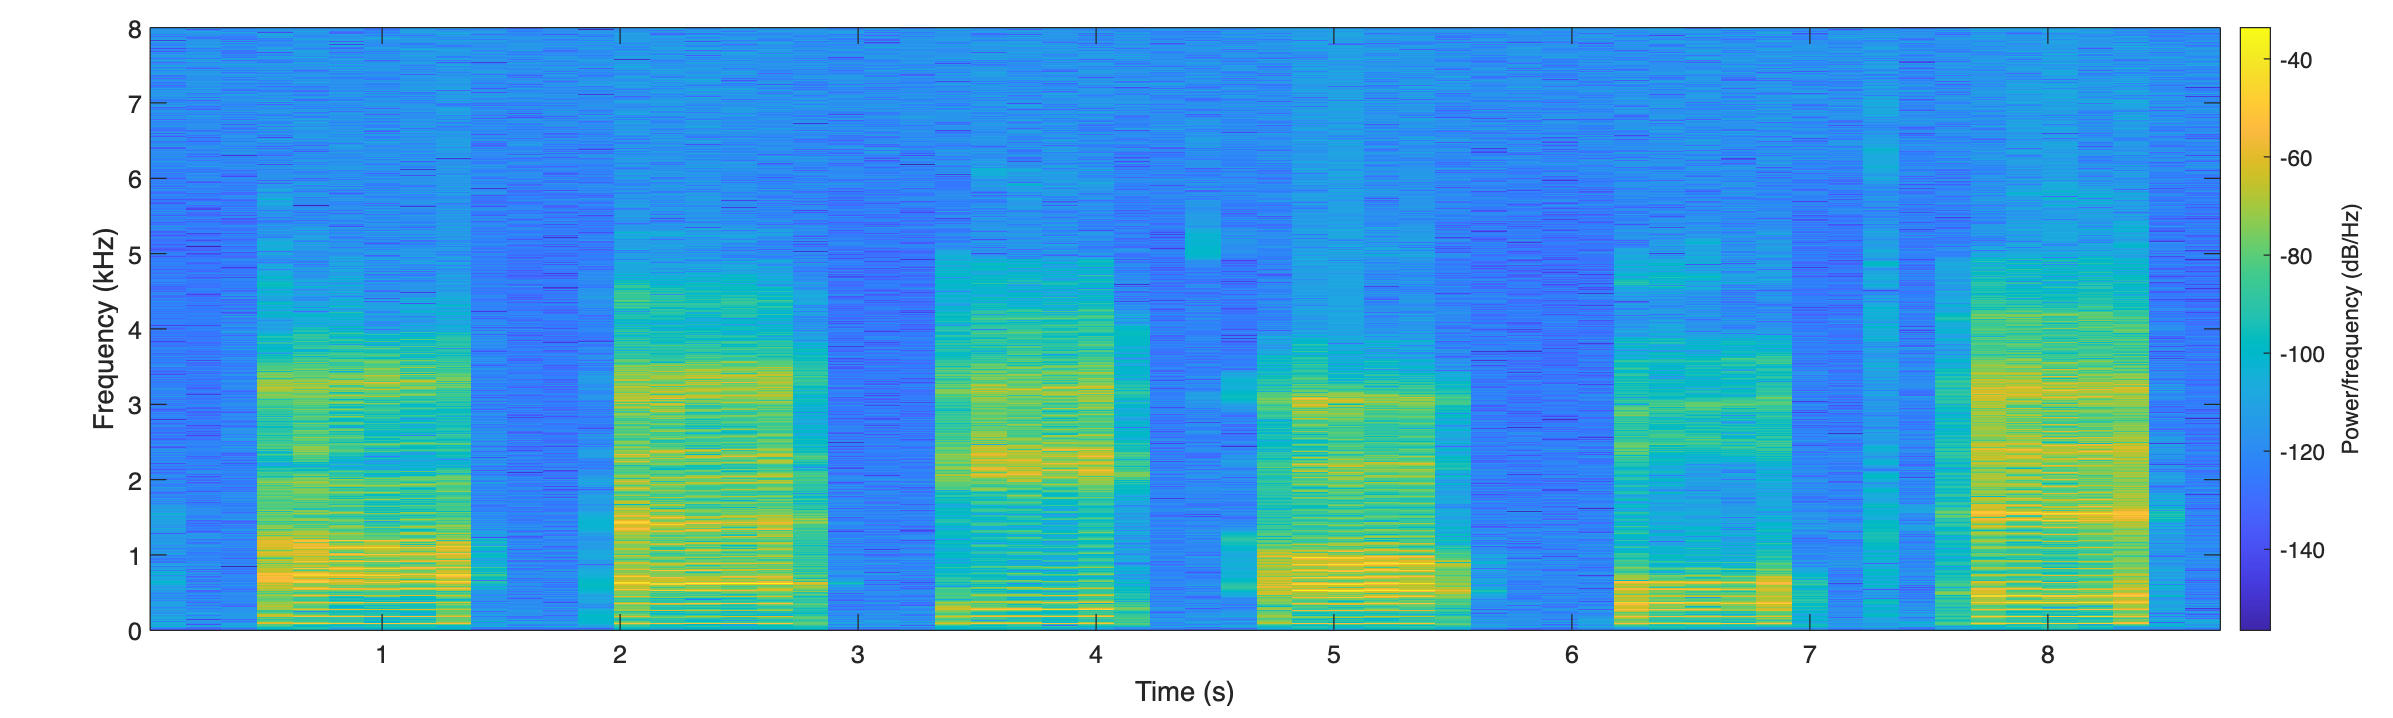

[x, fs] = audioread("aeiouy.wav");

win = round(fs * 0.2);

[s, f, t] = spectrogram(x, win, win / 4, [], fs, 'yaxis');

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
spectrogram(x, win, win/4, [], fs, 'yaxis');

### Etykietowanie danych

W kolejnych kolumnach macierzy znajdują się:

- numer okienka

- numer prążka

- częstotliwość prążka

- numer etykiety

Częstotliwość bazowa dla danego okienka wyznaczana jest przez podzielenie częstotliwości prążka przez jego numer.

sel = [
     5, 11, 1012, 1
     6, 11, 1006, 1
     7, 11, 1004, 1
     8, 11, 1012, 1
    
    15, 10,  880, 2
    16, 10,  884, 2
    17, 10,  888, 2
    18, 10,  890, 2
    
    24,  9,  840, 3
    25,  9,  845, 3
    26,  9,  830, 3
    27,  9,  834, 3
    
    33, 11,  966, 4 
    34, 11,  959, 4
    35, 11,  975, 4
    36, 11,  975, 4
    
    43,  6,  545, 5
    44,  6,  545, 5
    45,  6,  539, 5
    46,  6,  539, 5
    
    52,  7,  642, 6
    53,  7,  644, 6
    54,  7,  637, 6
    55,  7,  638, 6
];

Dodatkowo określamy same etykiety dla naszych danych:

labels = ['a', 'e', 'i', 'o', 'u', 'y'];

### Wyznaczenie wektorów cech

Prostą cechą dla głosek dźwięcznych jest rozkład energii sygnału w kolejnych harmonicznych częstotliwości bazowej (F0). Znając jej wartość można wyznaczyć położenie harmonicznych i odczytać z transformaty Fouriera ich amplitudę bądź energię.

% liczba harmonicznych do analizy
n_peaks = 20;

% liczba próbek uczących
n_frames = size(sel, 1);

% macierz z wektorami cech: każda kolumna to wektor dla kolejnej próbki
feats = zeros(n_frames, n_peaks);


for row = 1:n_frames
    % wyliczenie częstotliwości bazowej
    f0 = sel(row, 3) / sel(row, 2);

    % ekstrakcja ramki ze spektrogramu
    frame_id = sel(row, 1);
    frame = abs(s(:, frame_id));

    % odczyt wartości amplitudy dla kolejnych harmonicznych
    feats(row, :) = interp1(f, frame, (1:n_peaks) * f0);

    % normalizacja amplitud
    feats(row, :) = feats(row, :) / max(feats(row, :));
end

### Wizualizacja

Wektory cech

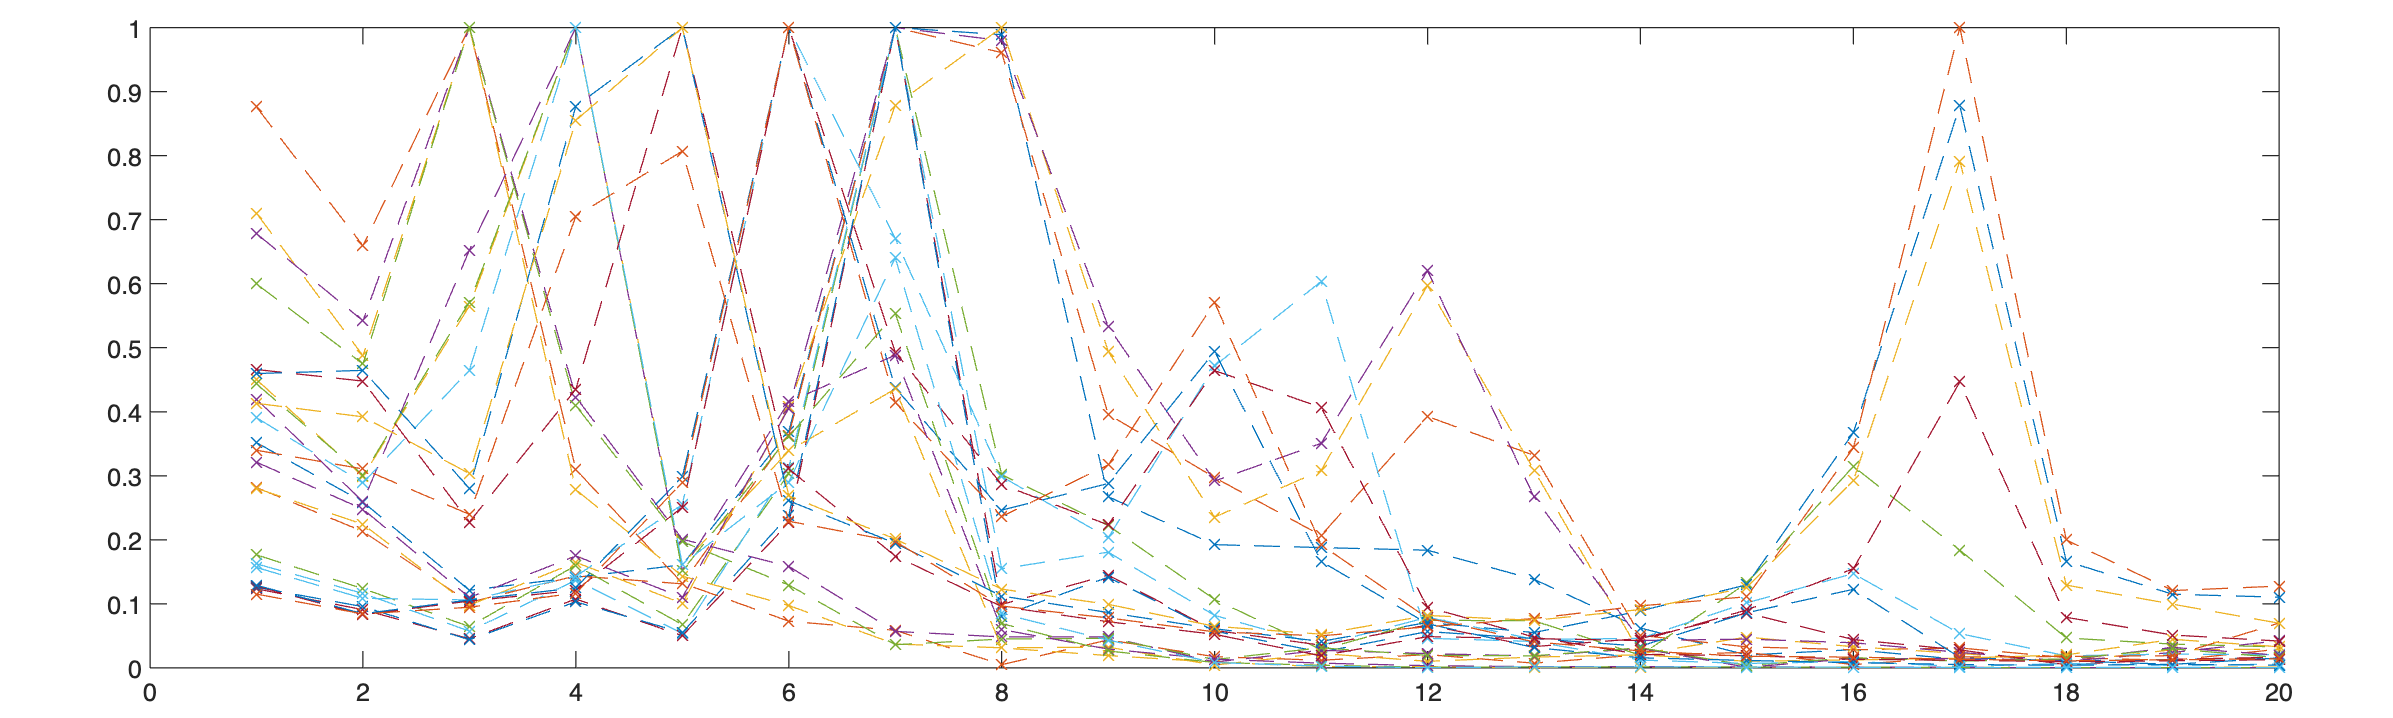

figure("Position", [0 0 1000 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
plot(feats', 'x--');

Wzajemne odległości między wektorami - wybór metryki ma znaczenie!

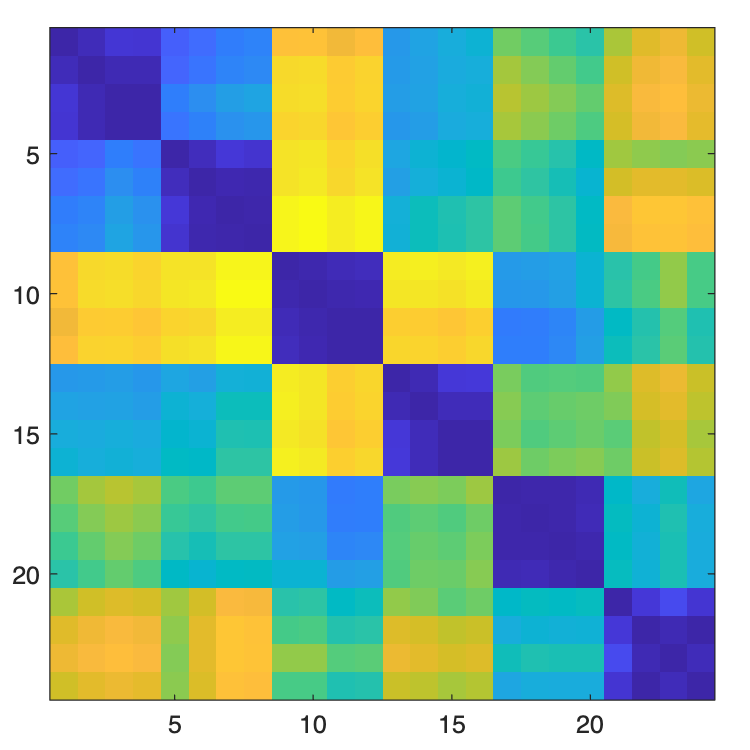

figure("Position", [0 0 300 300]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
% dist = pdist2(feats, feats, 'cosine');
imagesc(pdist2(feats, feats, 'cosine'));

## Analiza nagrania

### Wczytanie nagrania

[x, fs] = audioread("percepcja.wav");

### Segmentacja głosek dźwięcznych w nagraniu

Funkcja geVoicedSegments powinna zwracać macierz, w której każdy wiersz odpowiada znalezionej głosce dźwięcznej, a w kolumnach są po kolei:

- indeks pierwszej próbki 

- indeks ostatniej próbki

- częstotliwość bazowa

s = getVoicedSegments(x, fs);

### Wyznaczenie wektorów cech dla poszczególnych głosek

Algorytm identyczny z użytym do wyznaczenia cech wzorcowych:

- wyznaczenie spektrum sygnału i jego aplitudy

- wybór wartości odpowiadających harmonicznym

- normalizacja wartości

s_count = size(s, 1);

feat = zeros(s_count, n_peaks);
for seg = 1:s_count
    t1 = s(seg, 1);
    t2 = s(seg, 2);
    f0 = s(seg, 3);
    tmp = x(t1:t2);
    [f, A] = getAmp(tmp, fs);
    
    tmp_f = interp1(f, A, (1:n_peaks) * f0);
    feat(seg, :) = tmp_f / max(tmp_f);
end

### Odległości pomiędzy próbkami z nagrania a wzorcem

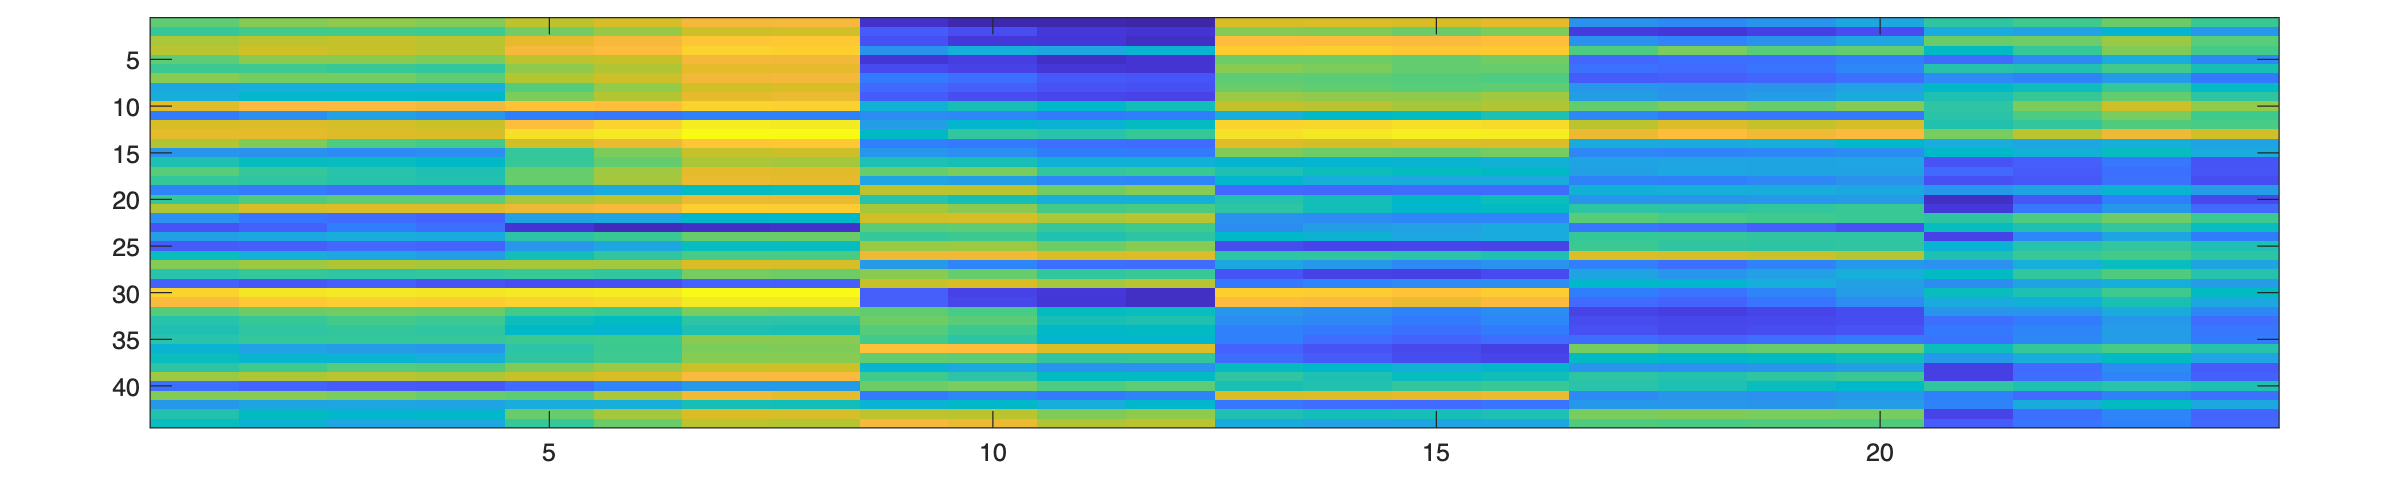

figure("Position", [0 0 1000 200]);
tiledlayout(1,1,'TileSpacing','Compact','Padding','Compact');
nexttile;
% dist = pdist2(feat, feats, 'cosine');
imagesc(pdist2(feat, feats, 'cosine'));

### Klasyfikacja próbek

ret = [];

for seg = 1:s_count
    query = feat(seg, :);
    cls = classify(query, feats, sel(:, 4));
    ret = [ret, labels(cls)];
end

ret

ret = 'iiiiiiiiiiuiiiiyyyoyyaeyoaioeiiuuuuooyyayoyy'

## Funkcje do implementacji

function s = getVoicedSegments(x, fs)
% lista segmentów dźwięcznych, opisana kolejno przez:
% - indeks pierwszej próbki
% - indeks ostatniej próbki
% - częstotliwość bazowa

    % s = [
    %         13400, 14200, 89.15
    %         32800, 33800, 92.80
    %     ];

    s = [];

    win = round(fs * 0.01);
    % win = round(fs * 0.1);
    
    ste = conv(x.^2, ones(1,win), 'same');
    ste = ste / max(ste); 
    
    str = sqrt(ste);

    lbls = zeros(1, length(str));
    lbls(str > 0.01) = 1;  


    num_windows = floor(length(x) / win); 
    
    zcr_values = zeros(1, num_windows); 
    
    for i = 1:num_windows
        segment = x((i-1)*win + 1 : i*win); 
        zcr_values(i) = zerocrossrate(segment);
    end
    
    zcr_threshold = 0.3; 

    for i = 1:num_windows
        start_idx = (i-1) * win + 1;
        end_idx = i * win;
        
        if zcr_values(i) < zcr_threshold 
            % lbls(start_idx:end_idx) = 2; 
            f0 = pitch(x(start_idx:end_idx), fs);
            if all(lbls(start_idx:end_idx)~=0) && f0 ~= 0
                s = [s; start_idx end_idx f0];
            end
            
        end
    end
end

function cls = classify(query, features, ids)
% klasyfikacja pojedynczej próbki
% - query: badany wektor cech Nx1
% - features: wektory treningowe (referencyjne) NxK
% - ids: identyfikatory klasy Nx1

    d = pdist2(query, features, 'cosine');
    [~, min_id] = min(d, [], 2);
    cls = ids(min_id);
end




function f0 = pitch(x, fs)

    % num_windows = floor(length(x) / win);
    % f_win = zeros(1, num_windows);
    % f0 = zeros(1,length(x));

    % for i = 1:num_windows
        % segment = x((i-1)*win + 1 : i*win); 
        segment = x; 
        f_max = 300;
        lag_min = fs / f_max;

        [c, lags] = xcorr(segment, "normalized");
        c = c(lags > lag_min);
        lags = lags(lags > lag_min);
        [pks, loc] = findpeaks(c, "MinPeakProminence", 0.2, "MinPeakWidth", 3);

        if length(loc) >= 2
            [~, index] = max(pks); 
            % f_win(i) =  fs / lags(loc(index));
            f0 =  fs / lags(loc(index));
        else
            f0 = 0;
        end
    % end

    % for i = 1:num_windows
    %     start_idx = (i-1) * win + 1;
    %     end_idx = i * win;
    % 
    %     f0(start_idx:end_idx) = f_win(i); 
    % 
    % end



end

## Funkcje pomocnicze

function [f, A] = getAmp(x, fs)
    L = floor(length(x) / 2) * 2;
    Y = fft(x);     % transformata Fouriera

    A = abs(Y);     % amplituda sygnału

    A = A/L;        % normalizacja amplitudy

    A = A(1:L/2+1); % wycięcie istotnej części spektrum
    A(2:end-1) = 2*A(2:end-1);

    f_step = fs/L;     % zmiana częstotliwości
    f = 0:f_step:fs/2; % oś częstotliwości do wykresu
end

function D = distEmd( X, Y )
    % source: http://www.cs.columbia.edu/~mmerler/project/code/pdist2.m

    Xcdf = cumsum(X,2);
    Ycdf = cumsum(Y,2);
    
    m = size(X,1);  n = size(Y,1);
    mOnes = ones(1,m); D = zeros(m,n);
    for i=1:n
      ycdf = Ycdf(i,:);
      ycdfRep = ycdf( mOnes, : );
      D(:,i) = sum(abs(Xcdf - ycdfRep),2);
    end

end